# Systemidentifikation - PT2 überdämpft

Regelungstechnik Labor - Vorbereitungsaufgabe 3.2

clear; clc; close all;

## 1) Daten laden

load('measurement_data.mat');  % Variable: raw_data_new
t     = raw_data_new(:,1);    % Zeit in s
u_in  = raw_data_new(:,2);    % Eingangsspannung in V
u_out = raw_data_new(:,3);    % Ausgangsspannung in V

## 2) Rohdaten plotten

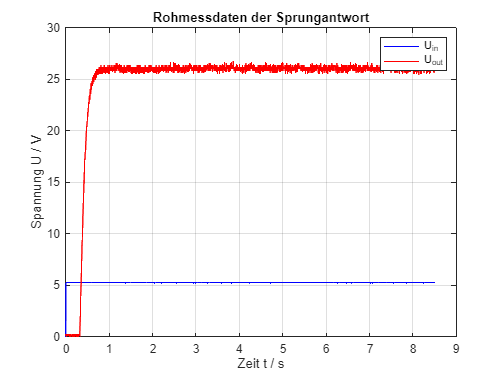

figure('Name','Rohdaten');
plot(t, u_in, 'b-', t, u_out, 'r-');
xlabel('Zeit t / s');
ylabel('Spannung U / V');
legend('U_{in}', 'U_{out}');
title('Rohmessdaten der Sprungantwort');
grid on;

## 3) Systemparameter bestimmen

U_step = u_in(find(u_in > 0.5, 1));      % Sprungamplitude
y_0    = u_out(1);                         % Anfangswert
y_end  = mean(u_out(end-100:end));         % Stationärer Endwert
K_raw  = (y_end - y_0) / U_step;          % Statische Verstärkung

fprintf('Sprungamplitude:  %.2f V\n', U_step);

Sprungamplitude:  5.24 V


fprintf('Anfangswert:      %.2f V\n', y_0);

Anfangswert:      0.20 V


fprintf('Stationärer Wert: %.2f V\n', y_end);

Stationärer Wert: 26.01 V


fprintf('Verstärkung K:    %.4f\n', K_raw);

Verstärkung K:    4.9248


## 4) Normierte Sprungantwort

y_norm = (u_out - y_0) / U_step;

## 5) PT2-Modell mit Totzeit fitten

% Startparameter: [K, tau1, tau2, Td]
p0 = [K_raw, 0.1, 0.03, 0.3];

% Untere und obere Grenzen
lb = [0,   0.001, 0.001, 0];
ub = [20,  5,     5,     2];

% Least-Square Fit mit lsqcurvefit
opts = optimoptions('lsqcurvefit', 'Display', 'off', 'MaxIterations', 5000);
p_fit = lsqcurvefit(@pt2_model, p0, t, y_norm, lb, ub, opts);

K    = p_fit(1);
tau1 = max(p_fit(2), p_fit(3));  % tau1 >= tau2
tau2 = min(p_fit(2), p_fit(3));
Td   = p_fit(4);

fprintf('\n--- Identifizierte PT2-Parameter ---\n');


--- Identifizierte PT2-Parameter ---


fprintf('K   = %.4f\n', K);

K   = 4.9344


fprintf('tau1 = %.4f s\n', tau1);

tau1 = 0.0931 s


fprintf('tau2 = %.4f s\n', tau2);

tau2 = 0.0253 s


fprintf('Td  = %.4f s\n', Td);

Td  = 0.3140 s


## 6) Übertragungsfunktion aufstellen

fprintf('\nÜbertragungsfunktion:\n');


Übertragungsfunktion:


fprintf('G(s) = %.4f / ((%.4f·s + 1)(%.4f·s + 1))\n', K, tau1, tau2);

G(s) = 4.9344 / ((0.0931·s + 1)(0.0253·s + 1))



% MATLAB tf-Objekt (ohne Totzeit)
num = K;
den = conv([tau1 1], [tau2 1]);
G_pt2 = tf(num, den);
fprintf('\nMATLAB tf:\n');


MATLAB tf:


G_pt2


G_pt2 =
 
            4.934
  --------------------------
  0.00236 s^2 + 0.1185 s + 1
 
Continuous-time transfer function.
Model Properties


## 7) Vergleichsplot: Messdaten vs. Modell

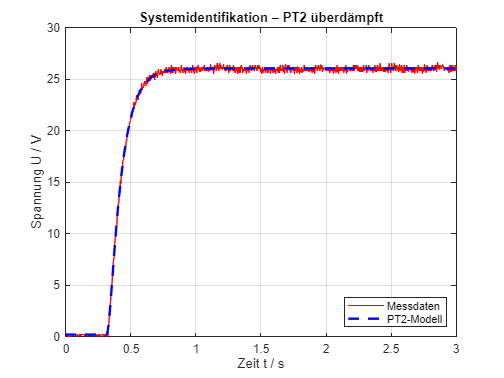

y_model = pt2_model(p_fit, t) * U_step + y_0;

figure('Name','Systemidentifikation');
plot(t, u_out, 'r-', 'DisplayName', 'Messdaten');
hold on;
plot(t, y_model, 'b--', 'LineWidth', 2, 'DisplayName', 'PT2-Modell');
hold off;
xlabel('Zeit t / s');
ylabel('Spannung U / V');
title('Systemidentifikation – PT2 überdämpft');
legend('Location','southeast');
grid on;
xlim([0 3]);

## 8) RMSE berechnen

rmse = sqrt(mean((u_out - y_model).^2));
fprintf('RMSE = %.4f V\n', rmse);

RMSE = 0.2402 V


## Hilfsfunktio

function y = pt2_model(p, t)
% PT2-Sprungantwort mit Totzeit
% p = [K, tau1, tau2, Td]
K    = p(1);
tau1 = p(2);
tau2 = p(3);
Td   = p(4);

y = zeros(size(t));
idx = t > Td;
t_eff = t(idx) - Td;

if abs(tau1 - tau2) < 1e-10
    % Doppelte Zeitkonstante (kritisch gedämpft)
    y(idx) = K * (1 - (1 + t_eff/tau1) .* exp(-t_eff/tau1));
else
    % Zwei verschiedene Zeitkonstanten (überdämpft)
    y(idx) = K * (1 - (tau1*exp(-t_eff/tau1) - tau2*exp(-t_eff/tau2)) / (tau1 - tau2));
end
end